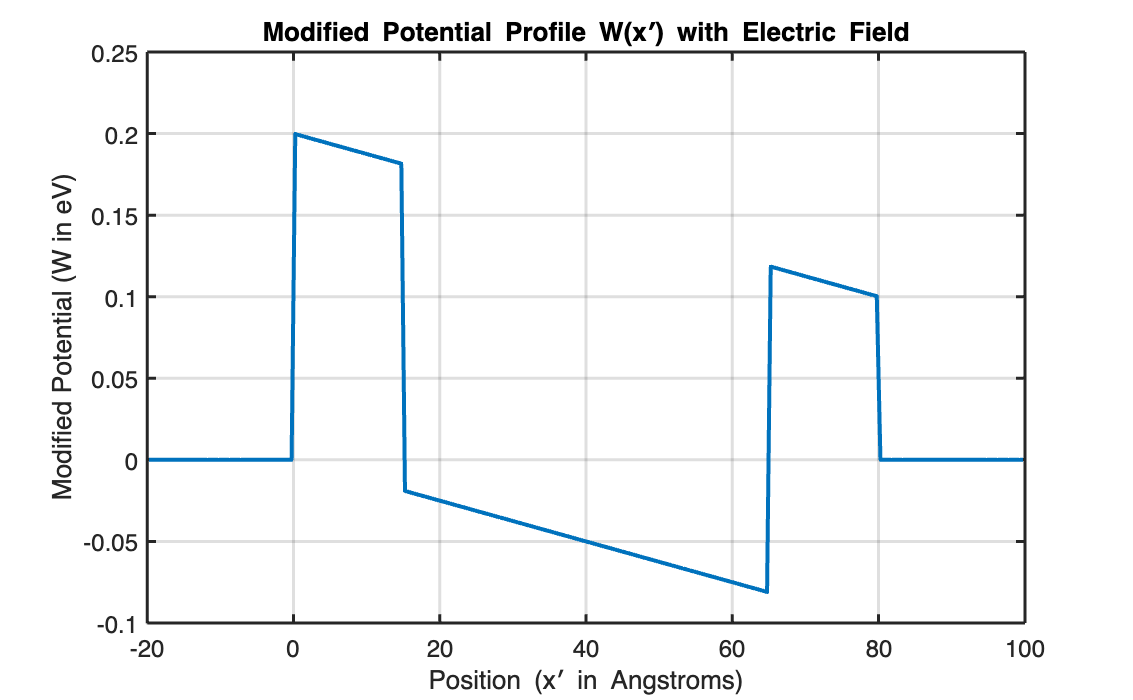

Lower energy bound (Ea) = 0.000000 eV
Upper energy bound (Eb) = 3.809982 eV


mystartdefaults
part_2

format long; % or format long e

recipunit = 1.0E+10;                               % done
ekinscale = ((hbar*recipunit)^2/(2*elm))/qel;      % done
tol = 1e-12;                                       % done
E_min = 0;                                         % done
E_max = 0.3;                                       % done
deltaE = 0.0005;                                   % done
E0 = E_min:deltaE:E_max;                           % done
R_values = zeros(length(E0), 1);                   % done
T_values = zeros(length(E0), 1);                   % done
A_values = zeros(length(E0), 1);                   % done
n = (x_prime_max - x_prime_min)/step_size;         % done

Create U and V

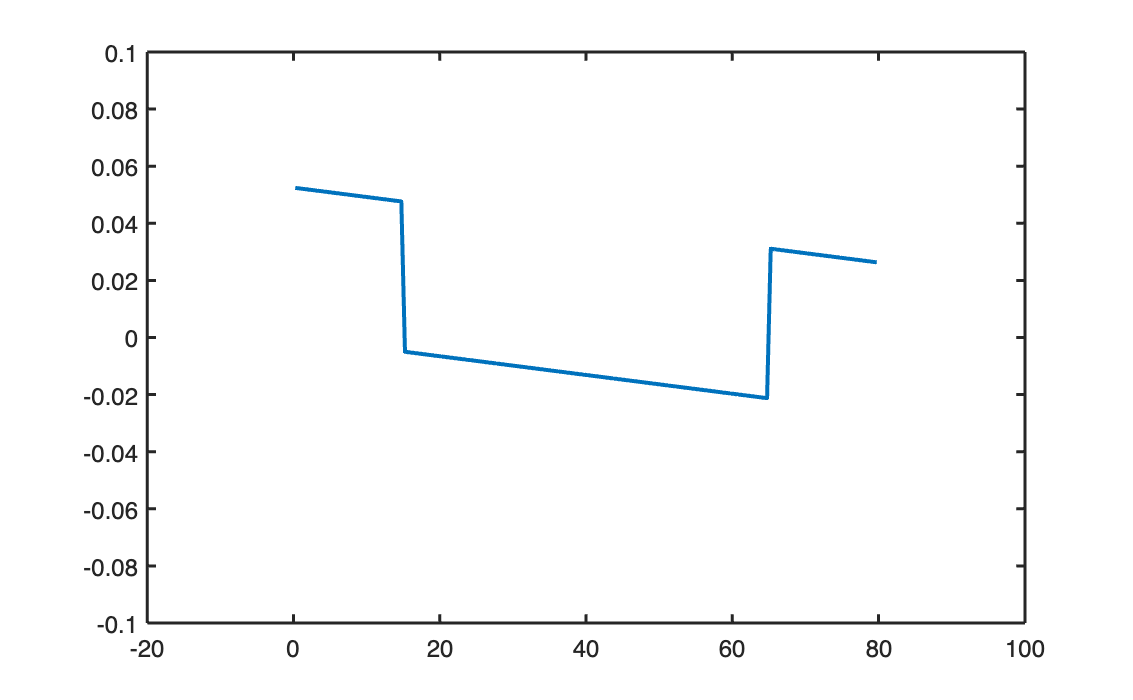

xp = zeros(n,1); % done
for i = 1:n % done
  xp(i) = x_prime_min + step_size/2 ... 
      + (i - 1) * step_size;                       % done
end 
U = zeros(n,1) + U0;                               % done
for i=1:n 
  if (xp(i) > 0 && xp(i) < 15)                     % done
    U(i) = U(i) + 0.2;
  end
  if (xp(i) > 65 && xp(i) < 80)                    % done
    U(i) = U(i) + 0.2;
  end
end
if (abs(U0 - max(U1)) > tol)                       % done
  E_field = -(max(U1) - U0)/ ...
  (x_prime_max - x_prime_min);                     % done
  for i = 1:n
    W_uu(i) = U(i) - E_field * xp(i);              % done
  end
end
V = W_uu/ekinscale;                                % done
plot(xp, V, 'LineWidth', 2);                       % done
xlim([-20 100]);                                   % done
ylim([-0.1 0.1]);                                  % done

Define G and find R, T and A

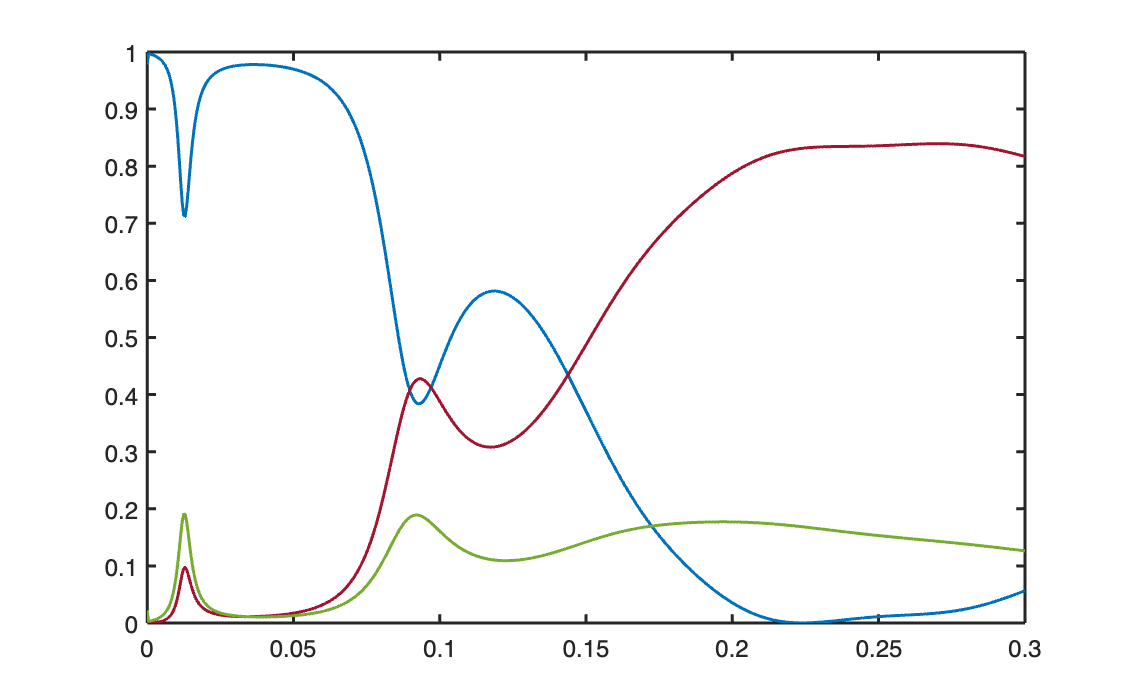

m=2;                                               % done
Phis = zeros(m,1);                                 % done
Phi = zeros(m,1);                                  % done
x = zeros(m,1);                                    % done
x(1) = x_prime_min - 1;                            % done
x(2) = x_prime_max + 1;                            % done
G0 = zeros(n,n);                                   % done
lifetime = 1e-9;                                   % done          
Gamma = hbar*(2*pi/lifetime/qel);                  % done
for k = 1:length(E0)                               % done
    E_0 = E0(k) - U0 ;                             % done
    E_1 = E0(k) - U0 - U1 ;                        % done
    ck_0 = sqrt((E_0 + 1i*Gamma)/ekinscale);       % done
    ck_1 = sqrt((E_1 + 1i*Gamma)/ekinscale);       % done
    rb = (ck_0 - ck_1) / (ck_0 + ck_1);            % done
    tb = (2 * ck_0)/ (ck_0 + ck_1);                % done
    Phi0p = tb * exp(1i * ck_1 * xp);              % done
    G0 = step_size * Green1(xp,xp',ck_0,ck_1);     % done
    T = eye(n,n) - G0 * diag(V);                   % done
    Phip = T\Phi0p;                                % done
    for i=1:m
      Phis(i) = 0;
      for j=1:n 
        Phis(i) = Phis(i) + step_size * Green1(x(i),xp(j),ck_0,ck_1) * V(j) * Phip(j); % check this
      end
      if x(i) > 0
          Phi(i) = rb * exp(-1i * ck_0 * x(i)) + Phis(i);                              % check this
      else
          Phi(i) = tb * exp( 1i * ck_1 * x(i)) + Phis(i);                              % check this
      end
    end
    R_values(k) = abs((rb * exp(-1i * ck_0 * x(1)) + Phis(1))/ (exp(1i * ck_0 * x(1))))^2;
    T_values(k) = abs((tb * exp( 1i * ck_1 * x(2)) + Phis(2))/ (exp(1i * ck_0 * x(2))))^2;
    A_values(k) = 1-R_values(k)-T_values(k);
end
spec_graph = plot(E0, R_values, E0, T_values, E0, A_values); % Plotting

function [G] = Green1(x, xp, k_0, k_1)
    tol = 1e-12;
    k_diff = (k_1 - k_0);
    junction = abs(k_diff) >= tol;
    k_sum = k_1 + k_0;
    reflex = k_diff / k_sum;

    G = zeros(length(x), length(xp));
    for ix = 1:length(x)
        for ixp = 1:length(xp)
            if ~junction
                % Homogeneous medium
                G(ix, ixp) = exp(1i * k_1 * abs(x(ix) - xp(ixp))) / (2 * 1i * k_1);
            else
                % Junction between two homogeneous media
                if x(ix) > 0 && xp(ixp) > 0
                    G(ix, ixp) = exp(1i * k_1 * abs(x(ix) - xp(ixp))) / (2 * 1i * k_1) + reflex * exp(1i * k_1 * (x(ix) + xp(ixp))) / (2 * 1i * k_1);
                elseif x(ix) < 0 && xp(ixp) > 0
                    G(ix, ixp) = exp(-1i * k_0 * x(ix) + 1i * k_1 * xp(ixp)) / (1i * k_sum);
                % Add conditions for other scenarios if needed
                end
            end
        end
    end
end

